# Classificació

## Netejar l'entorn

clc
close all
clear variables

## Parameters

samplePath = 'DemoPratFullAltMicro.png';
scenePath = 'DemoPratFullAlt.png';

% Co-matrix settings
cmDist = 1;
cmDir = [0 1; 1 0; 1 1; -1 1];
cmSym = true; % Symmetric (offsets [1 0] == [-1 0])

% Sliding Window settings
swStep = 10;

% Classification settings
nbest = 0; % Show best nbest cases. If 0, show cases better than threshold.
thr = 1;

% Presentation settings
maskAlpha = 0.65;

## Processem la mostra

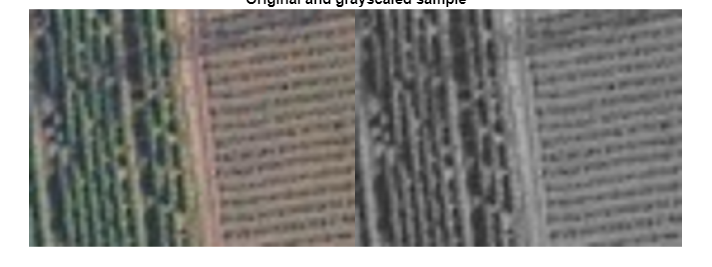

sampleImg = imread(samplePath);
sampleImgGs = im2gray(sampleImg);

figure
montage({sampleImg, sampleImgGs}), title('Original and grayscaled sample');


sampleProps = extractFeaturesGLCM(sampleImgGs, cmDir*cmDist, cmSym)

sampleProps =     0.7418    0.4980    0.9648    0.9964
    0.5382    0.6884    0.3977    0.3780
    0.1276    0.1399    0.1091    0.1058
    0.7379    0.7790    0.6599    0.6639


## Processem l'escena

sceneImg = imread(scenePath);
sceneImgGs = im2gray(sceneImg);

## Busquem coincidencies

swSize = size(sampleImgGs); % Sliding window must match sample size
sceneSize = size(sceneImgGs);

swNumY = floor( (sceneSize(1)-swSize(1)) / swStep );
swOffsetsY = swStep*(1:swNumY);

swNumX = floor( (sceneSize(2)-swSize(2)) / swStep );
swOffsetsX = swStep*(1:swNumX);

%tic
err = NaN(swNumY, swNumX);
parfor ny = 1:swNumY
    for nx = 1:swNumX

        y = swOffsetsY(ny);
        x = swOffsetsX(nx);

        swSample = sceneImgGs(y:(y+swSize(1)-1), x:(x+swSize(2)-1));
        swProps = extractFeaturesGLCM(swSample, cmDir*cmDist, cmSym);

        err(ny, nx) = sum( abs(sampleProps - swProps), 'all');

    end
end
%toc

## Find matching cases

if nbest ~= 0
    bestThr = sort(err(:));
    thr = bestThr(nbest);
end

fprintf('Found %i cases for threshold %.4f', sum(err(:) <= thr), thr)

Found 542 cases for threshold 1.0000

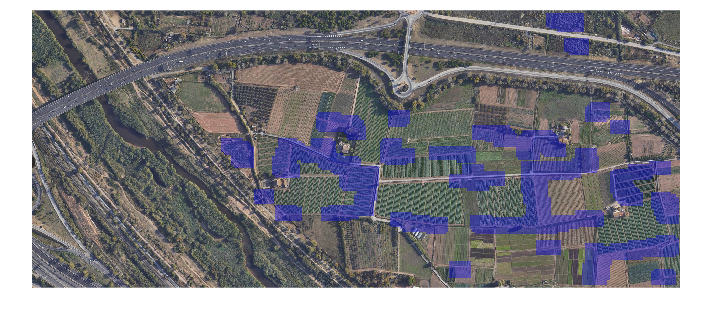


%tic
mask = false(sceneSize);
for ny = 1:swNumY
    for nx = 1:swNumX
        if err(ny, nx) <= thr

            y = swOffsetsY(ny);
            x = swOffsetsX(nx);

            mask(y:(y+swSize(1)-1), x:(x+swSize(2)-1)) = 1;

        end
    end
end
%toc

figure,
imshow( labeloverlay(sceneImg, mask, Transparency = maskAlpha));